## Polynomial interpolation - Ex. 8.2

clear all;
close all;
clc;

f = @(x) 1 ./ (1 + x.^2);
a = -5;
b = 5;

x = linspace(a, b, 1000);
plot(x, f(x), 'LineWidth', 2);
hold on;

Interpolation:

n = [5, 10, 20];

for i = 1:3
    xn = linspace(a, b, n(i)+1);
    Phin = polyfit(xn, f(xn), n(i));
    Phin_val = polyval(Phin, x);
    
    plot(x, Phin_val, '-', 'LineWidth', 2);
end

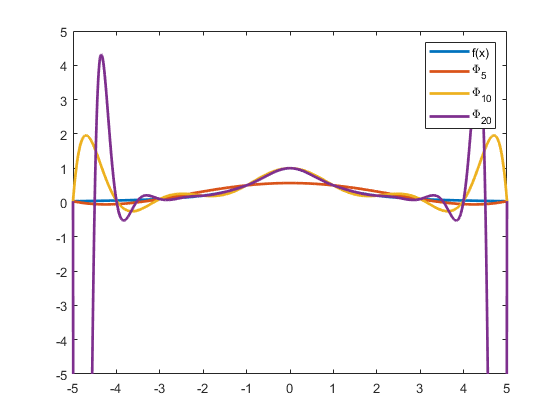

ylim([-5, 5]);
legend('f(x)', '\Phi_5', '\Phi_{10}', '\Phi_{20}');
hold off;